clear
load data2.mat
n=length(data.CzasLokalnyUTC0000);

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
all_data=length(X)

all_data = 516457

day=24*60*60*fs

day = 17280

t=T*(1:all_data);
X=X';
X=X(:,1:all_data);
size(X)

ans =            8      516457


X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

% figure
locs=compressorCycles(X(2,:));
locs=locs(2:end);
x = FeatureExtract(X_filtered(3,:),locs);
% plot((X_filtered(3,:)));hold on
% plot(locs,(X_filtered(3,locs)),'o');hold off
% title('Detection of peaks on Sonda temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
fridge_air_temp_p2p=x(1,:)-x(2,:);

indexContainer=cell(1);
indexContainer{1}=[];
set=1;
% figure
% hold on
TF = isoutlier(fridge_air_temp_p2p);

for i=2:length(x)
    
    if (TF(i)==0)
        % plot(locs(i-1):locs(i),(X_filtered(3,locs(i-1):locs(i))),"Color",'blue');
        % plot(locs(i),(X_filtered(3,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*fs*60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

load TrainingLargeDataset2.mat

% for i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y{i},params{i}]=GATrain(X(2,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
%         t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
% end

% save TrainingLargeDatasets y params

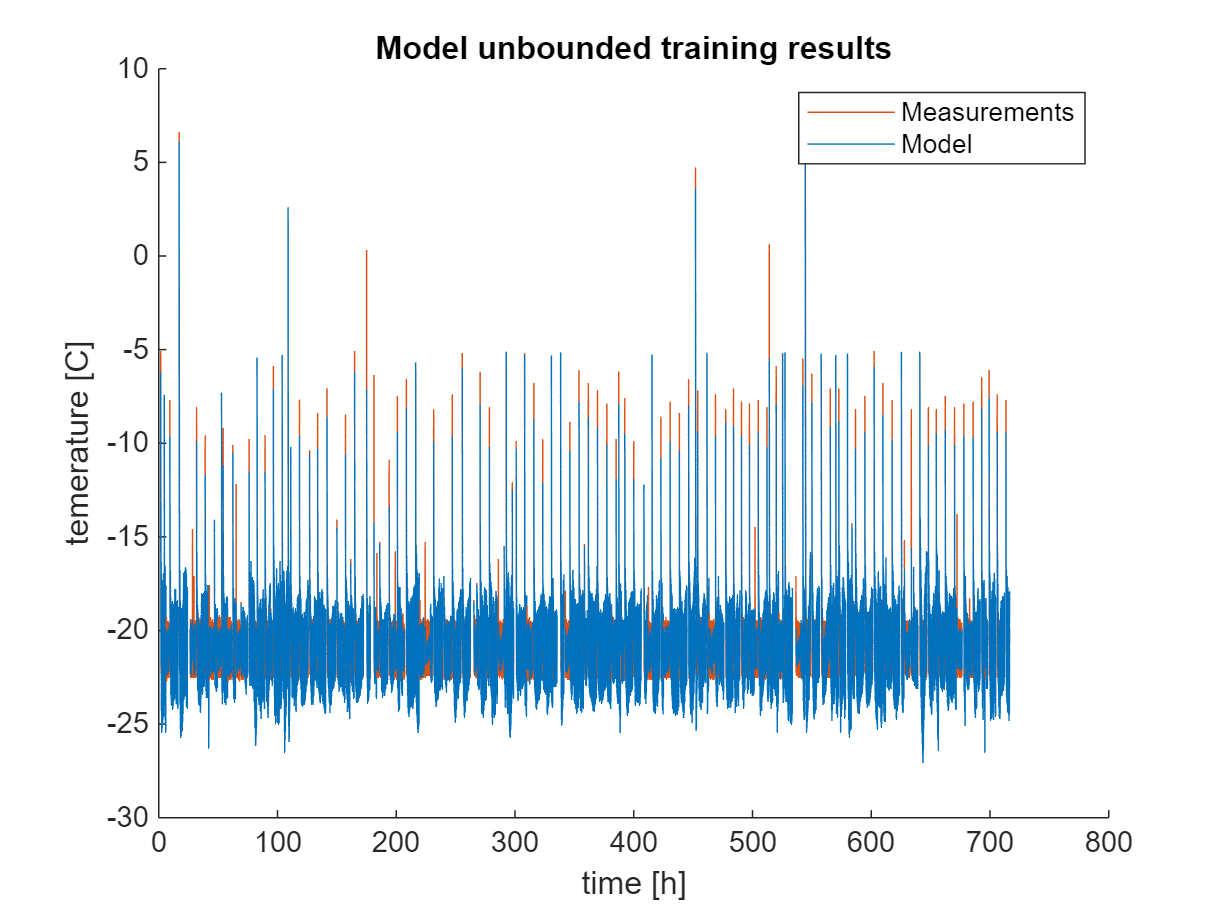

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

for i = 1:length(params)
resu(i,:)=params{i};
end


% figure
% plot3(resu(:,1),resu(:,2),resu(:,3),'o');
% grid on
% xlabel('G')
% ylabel('R')
% zlabel('C')
% title('Plot of parameter value results')
% % view(0,0)
% view(0,90)

Results analysys

for i = 1:length(params)
rmse_mat(i)=rmse(X_filtered(3,usableDataIndex{i})',y{i});
end

[rmse_mat_sorted, sort_indeces] = sort(rmse_mat);

TrainingFraction=0.8;  % percent of dataset used for training
TrainingNumber=floor(TrainingFraction*length(usableDataIndex));
TrainingData=usableDataIndex(1:TrainingNumber);
TestingData=usableDataIndex(TrainingNumber+1:end);

%     [y{i},params{i}]=GATrain(X(2,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
%         t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
% bestParameter=bestOfDataSet(TrainingData,params);


% function bestParameter=bestOfDataSet(TrainingSet,params,T)
TrainingSet=TrainingData;


averageRMSE=NaN(1,length(TrainingSet));
parfor j=1:length(TrainingSet) %for parameter set j
    RMSE_on_all=NaN(1,length(TrainingSet));
    for i=1:length(TrainingSet) %check rmse of j parameter set on all data chinks
        t_sim=T*(0:length(usableDataIndex{i})-1);
        RMSE_on_all(i) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{j}(1), params{j}(2), params{j}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
    end

    if any(isnan(RMSE_on_all), 'all')
        error('Array RMSE_on_all contains NaN values.');
    end

    averageRMSE(j)=mean(RMSE_on_all); %average rmse for j parameter set on all data chunks

end

if any(isnan(averageRMSE), 'all')
    error('Array averageRMSE contains NaN values.');
end

[~,ind] = min(averageRMSE);
bestParameter=params(ind);

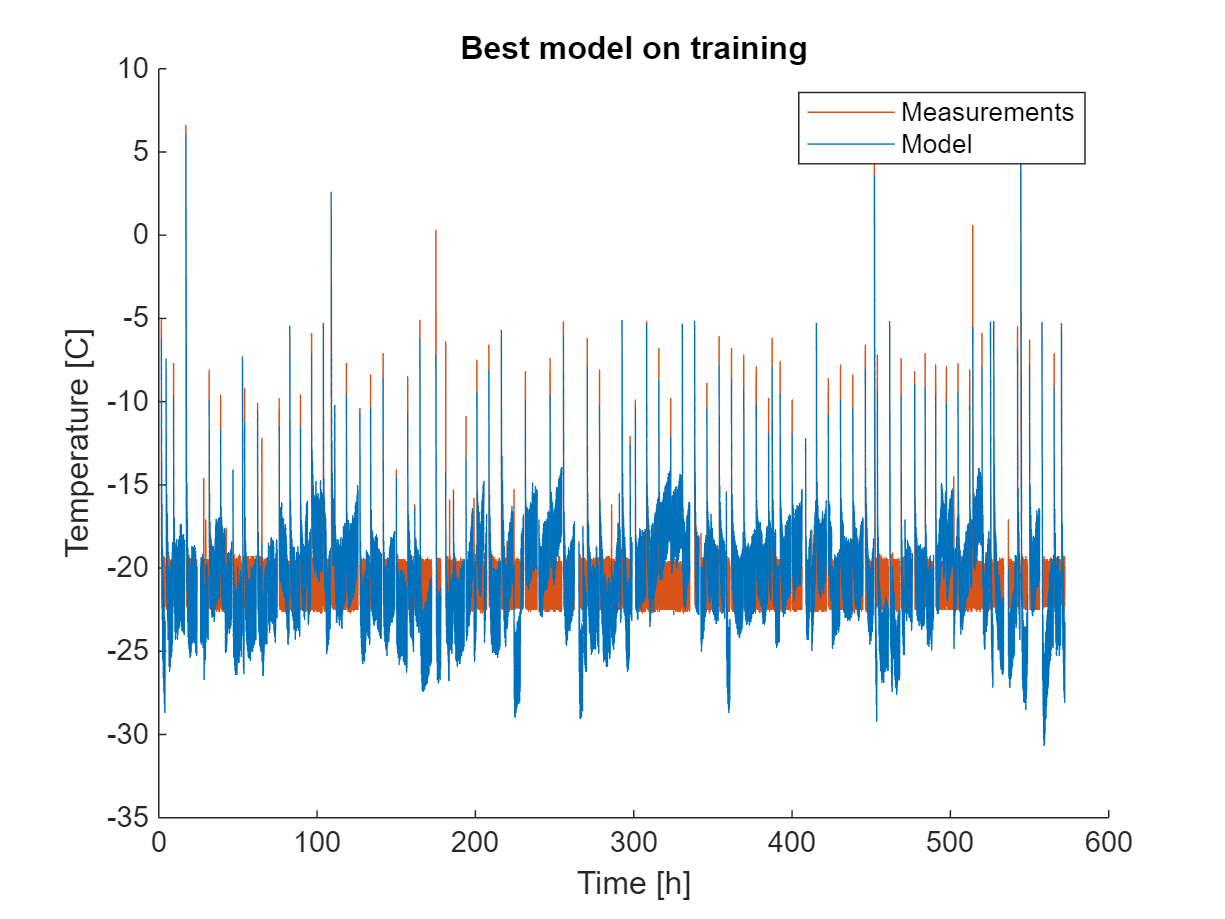


figure
hold on
for i = 1:TrainingNumber
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on training')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

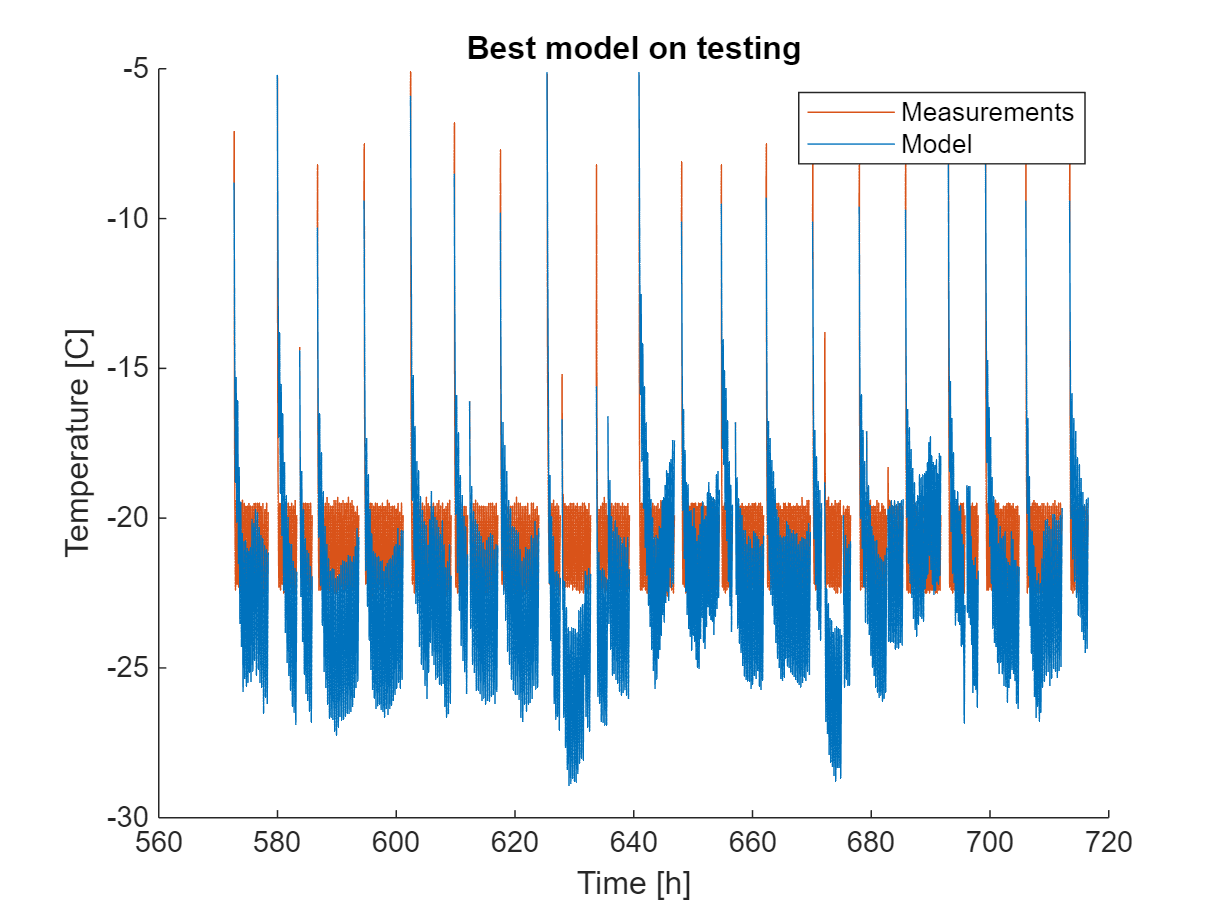


figure
hold on
for i = TrainingNumber+1:length(usableDataIndex)
% for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    y_tmp=ModelFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
            params{ind}(1), params{ind}(2), params{ind}(3),...
            t_sim, X_filtered(3,usableDataIndex{i}(1)))';

    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y_tmp,'Color','#0072BD')
end
hold off
title('Best model on testing')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('Measurements','Model')

min(averageRMSE)

ans = 2.1914

clear RMSE_on_all_testing
count=1;
for i=TrainingNumber+1:length(usableDataIndex)
    t_sim=T*(0:length(usableDataIndex{i})-1);
    RMSE_on_all_testing(count) = costFunction(-X(2,usableDataIndex{i})', X_filtered(1,usableDataIndex{i})',...
        params{ind}(1), params{ind}(2), params{ind}(3),...
        t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
   count=count+1;
end
mean(RMSE_on_all_testing)

ans = 2.4111

(mean(RMSE_on_all_testing)-min(averageRMSE))/min(averageRMSE)

ans = 0.1002

So the rmse on testing is 10% worst than on training 


% end
% figure;
% scatter3(resu(:,1),resu(:,2),resu(:,3), [], rmse_mat, 'filled');
% % Set the colormap
% colormap(jet); % You can use other colormaps like 'hot', 'parula', etc.
% 
% % Add colorbar
% 
% c=colorbar;
% c.Label.String = 'RMSE';
% grid on
% xlabel('G')
% ylabel('R')
% zlabel('C')
% title('Plot of parameter value results')
% view(0,0)
% view(0,90)
% view(90,0)

% i=100;
% sort_indeces(i)
% figure
% for i = 1 : length(y)
% % params_temp=params{i};    
% if length(y{i}) >5*60 && all(params{i} > [0 0 0])
% 
%     plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
%     hold on
%     plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
%     hold off
%     disp(i)
%     waitforbuttonpress;
% end
% end
% good_is=[1,6,42]
% i=1;
% figure
% % subplot(231)
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% % hold on
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% % hold off
% % % title('Model unbounded training results')
% % xlabel('time [h]')
% % ylabel('temerature [C]')
% % legend('Measurements','Model')
% subplot(121)
% i=4;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off
% xlabel('time [h]')
% ylabel('temerature [C]')
% legend('Measurements','Model')
% % subplot(233)
% % i=6;
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% % hold on
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% % hold off
% % xlabel('time [h]')
% % ylabel('temerature [C]')
% % legend('Measurements','Model')
% % subplot(234)
% % i=10;
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% % hold on
% % plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% % hold off
% % xlabel('time [h]')
% % ylabel('temerature [C]')
% % legend('Measurements','Model')
% subplot(122)
% i=30;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off
% xlabel('time [h]')
% ylabel('temerature [C]')
% legend('Measurements','Model')
% subplot(236)
% i=41;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off
% xlabel('time [h]')
% ylabel('temerature [C]')
% legend('Measurements','Model')
% figure
% % subplot(247)
% i=42;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off
% % subplot(241)
% i=47;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off
% i=78;
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),X_filtered(3,usableDataIndex{sort_indeces(i)}),'Color','#D95319')
% hold on
% plot(t(usableDataIndex{sort_indeces(i)})/(60*60),y{sort_indeces(i)},'Color','#0072BD')
% hold off